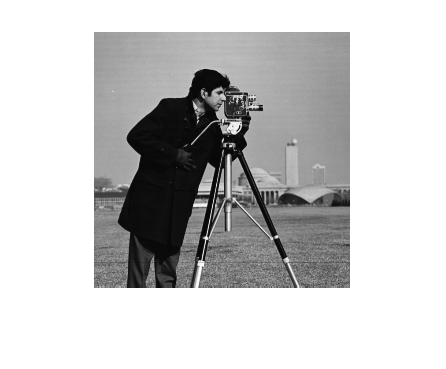

img = imread('images\cameraman.tif');
% the emphasis is on the middle pixel
img = im2double(img);
imshow(img)

r = random('Normal',0,0.2,[256,256]);
max(r)

ans =     0.5953    0.4668    0.6440    0.5998    0.5947    0.4926    0.5615    0.5069    0.4972    0.5346    0.5797    0.5708    0.5279    0.6499    0.5426    0.5443    0.5616    0.4951    0.5766    0.6210    0.4844    0.5791    0.5787    0.6020    0.6628    0.5934    0.4275    0.4372    0.4962    0.6959    0.5989    0.5327    0.7836    0.5777    0.5852    0.5466    0.5782    0.5252    0.4873    0.4835    0.5950    0.6250    0.6740    0.4730    0.4823    0.5877    0.6519    0.6161    0.8211    0.5186


min(r)

ans =    -0.5987   -0.6297   -0.5003   -0.5593   -0.4823   -0.7205   -0.5072   -0.6098   -0.6091   -0.5171   -0.6526   -0.5345   -0.5073   -0.6540   -0.6936   -0.5960   -0.5670   -0.5929   -0.5455   -0.5446   -0.6737   -0.5502   -0.7138   -0.5063   -0.5772   -0.5330   -0.6711   -0.4954   -0.5316   -0.7320   -0.5117   -0.6536   -0.5707   -0.6164   -0.6334   -0.5391   -0.7084   -0.4029   -0.5533   -0.5197   -0.5741   -0.4846   -0.5567   -0.7578   -0.6154   -0.3845   -0.4865   -0.5269   -0.5161   -0.5999


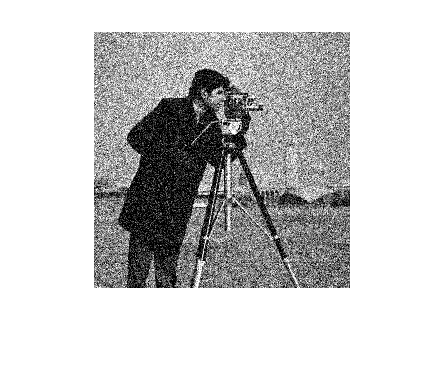

img_noise = img + r;
imshow(img_noise)

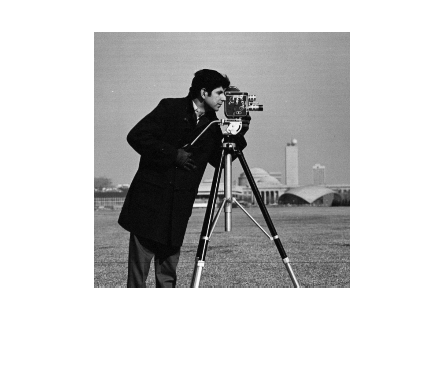

img = imread('images\cameraman.tif');
% standard deviation of intensity level
noise_sigma = 64;
img = im2double(img);
img_noise_cum = zeros(size(img));
for i=1:1000
    noise = random('Normal',0,noise_sigma/256,[256,256]);
    img_noise = img + noise;
    img_noise_cum = img_noise_cum + img_noise;
end

img_denoise = img_noise_cum/1000;
imshow(img_denoise)